syms omega1 omega2 theta1 theta2 c L1 m1 m2 g L2

eqs = [omega1;
    omega2;
    -c*omega1 + (-g*(2*m1 + m2)*sin(theta1) - m2* g*sin(theta1 - 2*theta2) - 2*sin(theta1 - theta2)*m2*(omega2^2 * L2 + omega1^2*L1 *cos(theta1 - theta2)))/(L1*(2*m1+m2 - m2*cos(2*theta1 - 2*theta2)));
    2* sin(theta1 - theta2)*(omega1^2 * L1 * (m1 + m2) + g*(m1+m2)*cos(theta1) + omega2^2 * L2 * m2*cos(theta1 - theta2))/(L2 * (2*m1 +m2 - m2 *cos(2*theta1 - 2*theta2)))];

J = jacobian(eqs,[theta1,theta2,omega1,omega2]);
c_val = 0.1;
L1_val = 2;
L2_val = 1;
m1_val = 1;
m2_val = 2;
g_val =10;
f = subs(J,[c, L1, L2, m1, m2, g], [c_val,L1_val,L2_val,m1_val,m2_val,g_val]);
F = subs(eqs,[c, L1, L2, m1, m2, g], [c_val,L1_val,L2_val,m1_val,m2_val,g_val]);

T =10;
N =400;
h = T/(N-1);
time = 0:h:T;
I = eye(4);
U0 = [pi-0.1,0,0,0]';
U_evalution = zeros(4,N);
U_evalution(:,1) = U0;
U = U0;
Eigens_evalution = zeros(4,N-1);
for i = (2:N)
    fn = double(subs(f,[theta1,theta2,omega1,omega2],U'));
    Fn = double(subs(F,[theta1,theta2,omega1,omega2],U'));
    dE = (I-h*fn)\(h*Fn);
    U = U + dE;
    U_evalution(:,i) = U;

    Eigens_evalution(:,i -1) = eig(fn);
end

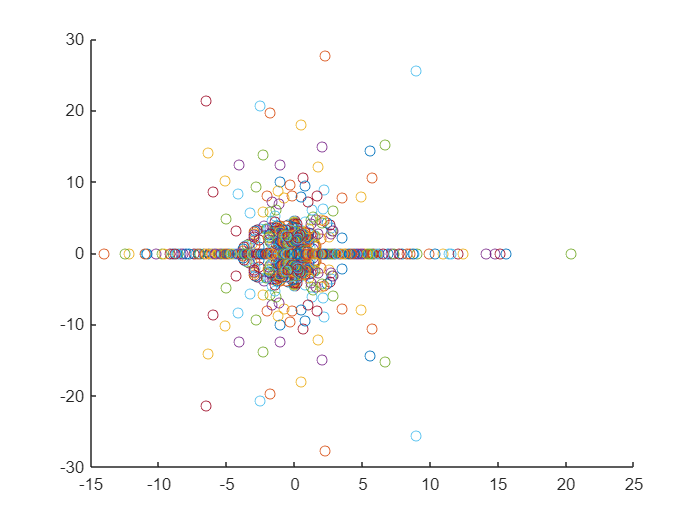

for i = 1:N-1
    scatter(real(Eigens_evalution(:,i)),imag(Eigens_evalution(:,i)));
    hold on 
end
hold off

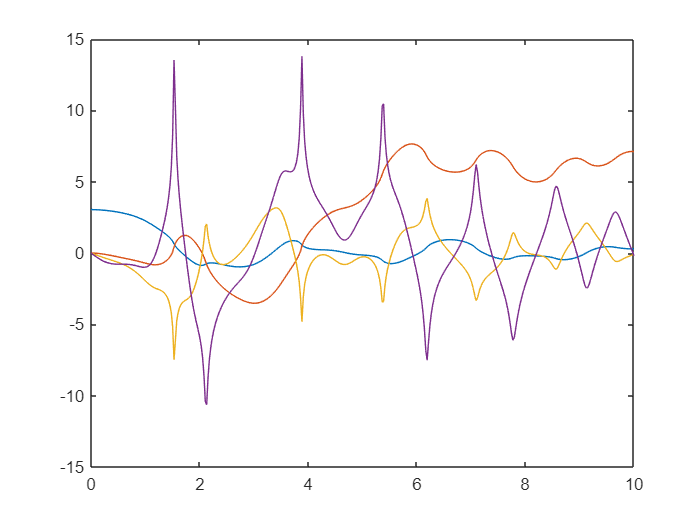

plot(time,U_evalution)

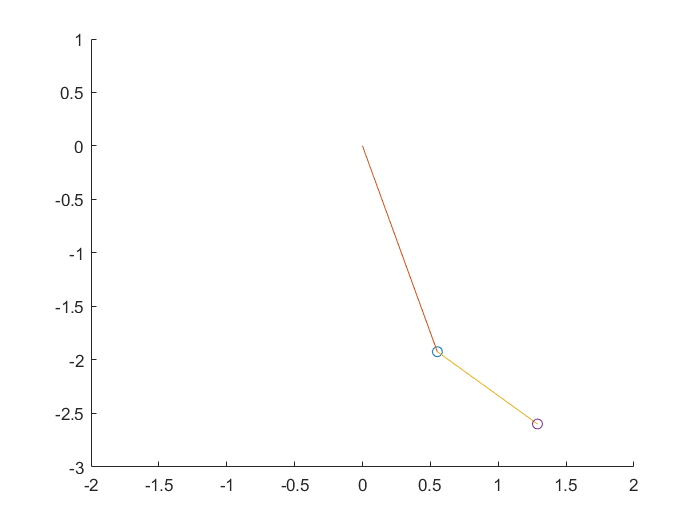

% it is movie
for i = 1:N
    phi1 =U_evalution(1,i);
    phi2 =U_evalution(2,i);
    A1 = [sin(phi1)*L1_val,-cos(phi1)*L1_val];
    A2 = A1+[sin(phi2)*L2_val,-cos(phi2)*L2_val];
    scatter(A1(1),A1(2));
    hold on
    plot([0,A1(1)],[0,A1(2)])
    plot([A2(1),A1(1)],[A2(2),A1(2)])
    scatter(A2(1),A2(2));
    xlim([-2,2])
    ylim([-3,1])
    hold off
    pause(0.01);

end